ImageFile = 'charles-forerunner-378.png';
sizeWork = [768 1280]/4;

% I = (SmartResize(imread(ImageFile), sizeWork));
im = imread(ImageFile);
offset = [400, 1000];
I = im(offset(1,1):offset(1,1)-1+sizeWork(1,1), offset(1,2):offset(1,2)-1+sizeWork(1,2));

figure
imshow(I)
ImageData = cell(0);

for i = 1:64:sizeWork(1,1)
    for j = 1:64:sizeWork(1,2)
        
        ImageData{end+1} = I(i:i+63, j:j+63);
        
    end
end
figure
montage(ImageData, 'Size', [3, 5], 'BorderSize', [2, 2], 'BackgroundColor',[1,0.3,0.2])


        for i= 1:size(ImageData,2)
            
            imwrite(imresize(ImageData{i},[64 64]), 'temp.jpeg', 'Quality',75)
           
            f = fopen('temp.jpeg');
            temp = string(dec2hex(fread(f)));
            fclose(f);
            
            Data = strcat(temp{:});
            FrameStartIndx = strfind(Data, 'FFDA')+4;
            HeaderData{i} = Data(1:FrameStartIndx-1);

            
        end
            
strcmpi(HeaderData{1}, HeaderData{2})

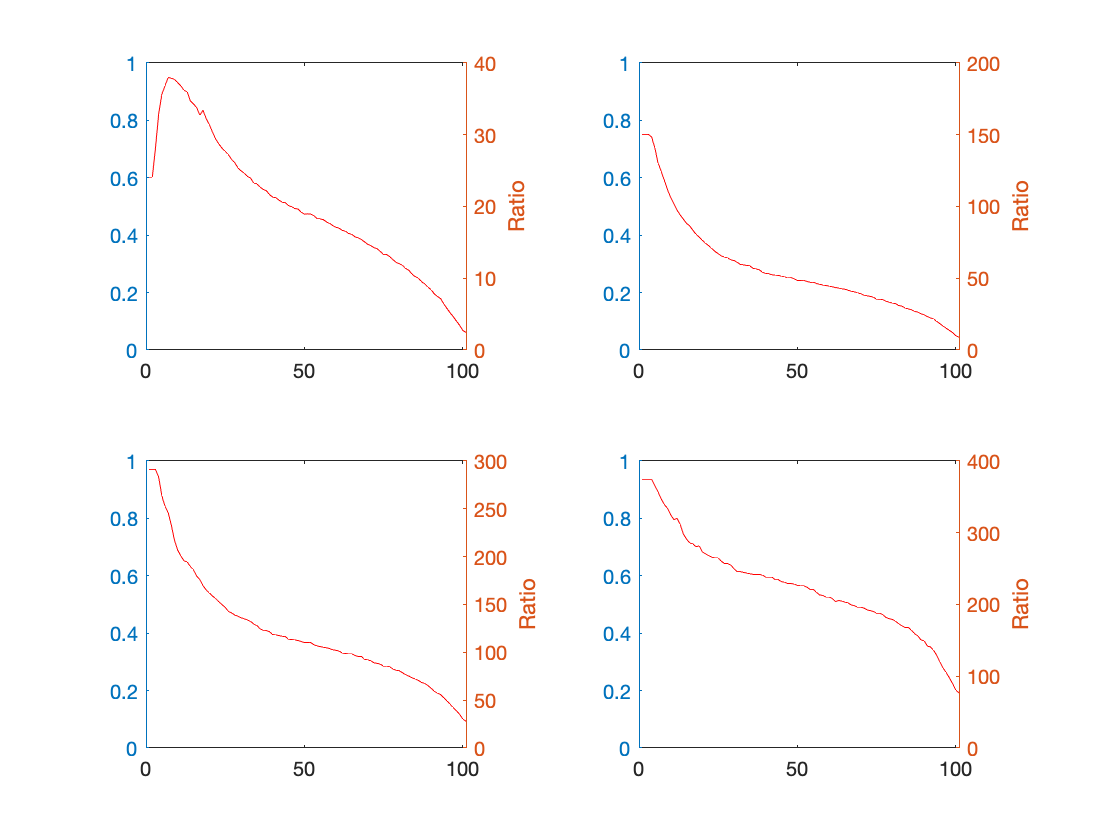

    for Q = 1:100
            
            imwrite(imresize(ImageData{5},[64 64]), 'temp.jpeg', 'Quality',Q)
           
            f = fopen('temp.jpeg');
            temp = string(dec2hex(fread(f)));
            fclose(f);
            
            Data = strcat(temp{:});
            FrameStartIndx = strfind(Data, 'FFDA')+4;
            HeaderData{Q} = Data(1:FrameStartIndx-1);
            
            QStartIndx = strfind(Data, 'FFDB')+4;
            QEndIndx = strfind(Data, 'FFC0')-1;
            QData{Q} = Data(QStartIndx(1):QEndIndx(1));
            
            HStartIndx = strfind(Data, 'FFC4')+4;
            HEndIndx = strfind(Data, 'FFDA')-1;
            HData{Q} = Data(HStartIndx(1):HEndIndx(1));

    end
    
    QData = transpose(QData);
    HData = transpose(HData);
    
    strcmpi(HData{1}, HData{2})


SCALES = [1 2 4 8];

for s = 1: length(SCALES)
    
    S = SCALES(s);
    
    for Q = 0:100
        
        for i= 1:size(ImageData,2)
            
            imwrite(imresize(ImageData{i},[64 64]./S), 'temp.jpeg', 'Quality',Q)
%             SSIM(s,Q+1,i) = ssim(imresize(imread('temp.jpeg'), [64 64]), ImageData{i});
%             PSNR(s,Q+1,i) = psnr(imresize(imread('temp.jpeg'), [64 64]), ImageData{i});
%             
            calcQ(s,Q+1,i,:) =  reshape(table2array(clcImageQuality(imresize(imread('temp.jpeg'), [64 64]), ImageData{i},'ALL')), [1,1,1,7]);
            
            f = fopen('temp.jpeg');
            temp = string(dec2hex(fread(f)));
            fclose(f);
            
            Data = strcat(temp{:});
            FrameStartIndx = strfind(Data, 'FFDA')+4;
            FrameData = Data(FrameStartIndx:end-2);
            CompressedBytes(s,Q+1,i) = length(FrameData)/2;
            
        end
            
        
    end
    
end


Metrics = {'SSIM', 'PSNR', 'VIF', 'ICID', 'SPEED', 'SMAD', 'SRRED'};

mm = 7;
QMetricValue = calcQ(:,:,:,mm);
Metric = Metrics{mm};

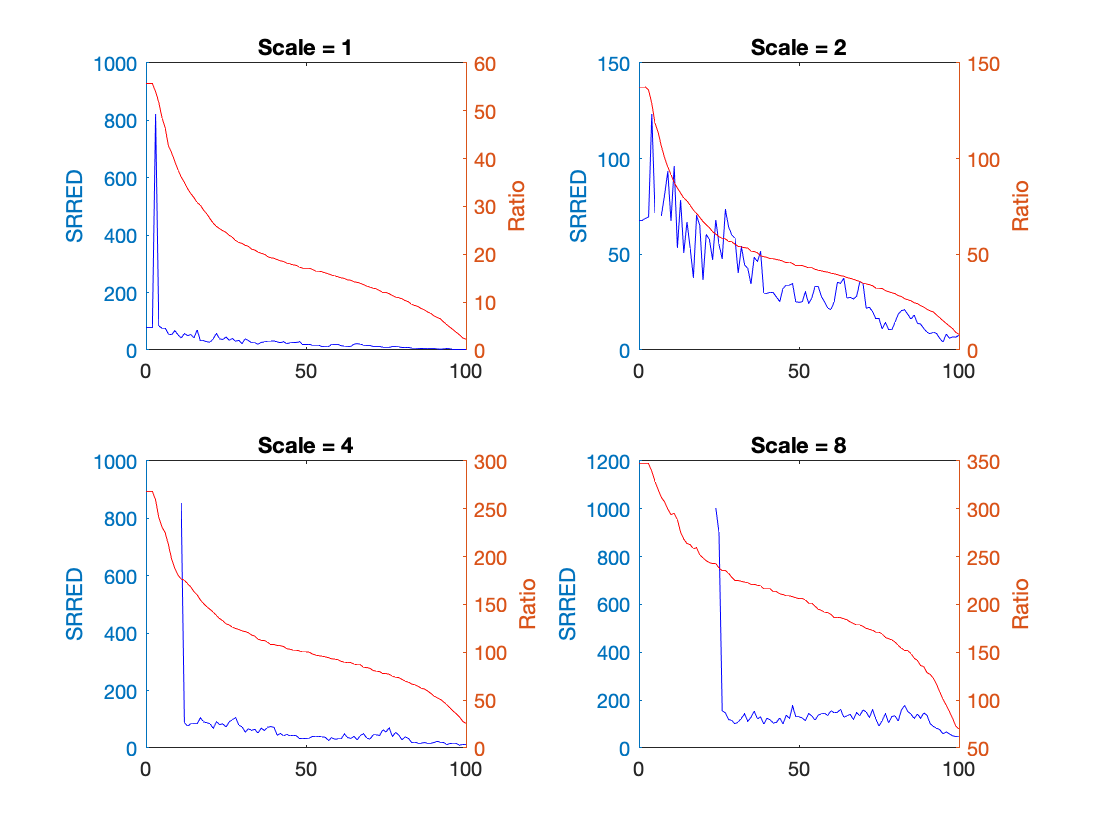

f = figure;
for i =1:4
  
    subplot(2,2,i)
    
    yyaxis right
    plot(0:100,(64*64)./(mean(CompressedBytes(i,:,:),3)), 'r');
    ylabel('Ratio');
%     hold on
%     plot(0:100, ones(1,101)*108, '--*m');
%     plot(0:100, ones(1,101)*54, '--*m');
%     plot(0:100, ones(1,101)*27,'--*m');
%     hold off
%     plot(mean(PSNR(i,:,:),3), 'g')

    yyaxis left
    plot(0:100, mean(QMetricValue(i,:,:),3), 'b')
    ylabel(Metric)
%     ylim([0 150])
    
    title(['Scale = ' num2str(SCALES(i)) ])
%     hold on
%     if i>1
%         yyaxis right
%         plot(0:100, ones(1,101)*max((64*64)./(mean(CompressedBytes(i-1,:,:),3))), '--g')
%        
%         
%          yyaxis left
%         plot(ones(1,101).*find((mean(QMetricValue(i,:,:),3) - mean(QMetricValue(i-1,1,:),3)) >= 0, 1), linspace(min(mean(QMetricValue(i,:,:),3)),max(mean(QMetricValue(i,:,:),3)),101), '--g');
%        
%         
%     end
    hold off
end

saveas(f, [Metric '_avg.png']);

for ff = 1:size(ImageData,2)  
f = figure;
  N = ff;
for i =1:4
  
    subplot(2,2,i)
    
    yyaxis right
    plot(0:100,(64*64)./(mean(CompressedBytes(i,:,N),3)), 'r');
    ylabel('Ratio');
%     plot(mean(PSNR(i,:,:),3), 'g')

    yyaxis left
    plot(0:100, mean(QMetricValue(i,:,N),3), 'b')
    ylabel('SSIM')
    
    title(['Scale = ' num2str(SCALES(i)) ])
    
       hold on
    if i>1
        yyaxis right
        plot(0:100, ones(1,101)*max((64*64)./(mean(CompressedBytes(i-1,:,N),3))), 'g')
        
        
         yyaxis left
        plot(ones(1,101)*find((mean(QMetricValue(i,:,N),3) - mean(QMetricValue(i-1,1,N),3)) >= 0, 1), linspace(min(mean(QMetricValue(i,:,N),3)),max(mean(QMetricValue(i,:,N),3)),101), 'g');
       
        
    end
    hold off
    
    
end

    saveas(f, ['Ratio4_' num2str(ff) '.png']);
end

for i = 1:size(ImageData,2) 
    
    DCT{i} = abs(dct2(ImageData{i}));
    [A{i}, H{i}, V{i}, D{i}] = haart2(ImageData{i},1);
end

for i = 1:size(ImageData,2)  
    
  f = figure;
   
   subplot(2,3,1)
   imshow(ImageData{i})
   title('Image');
   
   subplot(2,3,2)
   imagesc(DCT{i});
   title('DCT');
   
   subplot(2,3,3)
   imagesc(A{i});
   title('A');
   
   subplot(2,3,4)
   imagesc(H{i});
   title('H');
 
   subplot(2,3,5)
   imagesc(V{i});
   title('V');
   
   subplot(2,3,6)
   imagesc(D{i});
   title('D');
   
   saveas(f,['Transforms4_' num2str(i) '.png'])
   
end

imwrite(imresize(ImageData{8},[64 64]./2), 'temp_8_2_Q_0.jpeg', 'Quality',0);
imwrite(imresize(ImageData{8},[64 64]./2), 'temp_8_2_Q_10.jpeg', 'Quality',10);

IMG{1} = imresize(imread('temp_8_2_Q_0.jpeg'), [64 64]);
IMG{2} = imresize(imread('temp_8_2_Q_10.jpeg'), [64 64]);
IMG{3} = ImageData{8};

figure
montage(IMG)
